## Radar parameters

clear all;
close all;
clc;

GHz=1e+9;
MHz=1e+6;
us=1e-6;
c = physconst('LightSpeed'); %speed of light
BW = 150*MHz; %150M带宽
fc = 77*GHz; % carrier frequency
numADC = 256; % # of adc samples
numChirps = 256; % # of chirps per frame
%CPI Coherent Processing Interval 
%相干处理间隔，CPI内通常有固定的PRI和雷达频率，并且发射波形相同，以便进行多普勒测量。
numCPI = 10;  %256chirp构成一帧，共10帧

%采样参数设置
T = 10*us; % PRI pulse repeat interval/frequency，脉冲重复频率，
PRF = 1/T;%脉冲周期频率
F = numADC/T; % sampling frequency
dt = 1/F; % sampling interval
slope = BW/T; %调频系数
lambda = c/fc; 
N = numChirps*numADC*numCPI; % total # of adc samples,为什么要乘CPI
t = linspace(0,T*numChirps*numCPI,N); % time axis, 单位是？
% t= 0:dt:dt*numADC*numChirps-dt;
t_onePulse = 0:dt:dt*numADC-dt;


$$V_{max}=\frac{\lambda_c}{4T}\\
V_res=\\
R_max=\\
R_res=\\
\theta_res=$$


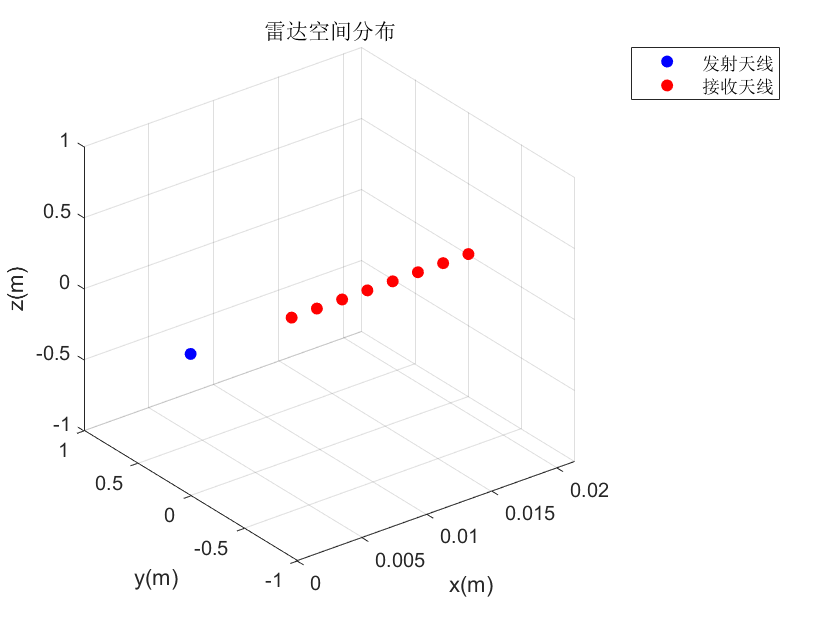

%雷达坐标，分辨率以及天线参数设置
numTX = 1;
numRX = 8;

%最大不模糊速度
Vmax = lambda/(T*4); % Max Unamb velocity m/s
%速度分辨率
dV = lambda/(2*numChirps*T); % velocity resol, lambda/(2*framePeriod)
%最大不模糊距离（采样频率）
Rmax = F*c/(2*slope); % TI's MIMO Radar doc
%距离分辨率
dR = c/(2*BW); % range resol

%Rmax2 = c/2/PRF; % lecture 2.3
%DFmax = 1/2*PRF; % = Vmax/(c/fc/2); % Max Unamb Dopp Freq

%接收天线间距为基线长度lambda/2 m
d_rx = lambda/2; % dist. between rxs
%发射天线间距
d_tx = 4*d_rx; % dist. between txs

%% Targets
%以雷达为中心，雷达波束为正北方向建立二维平面坐标系
%雷达空间分布

figure;
tx_loc = cell(1,numTX);
for i = 1:numTX
   tx_loc{i} = [(i-1)*d_tx 0 0];
   scatter3(tx_loc{i}(1),tx_loc{i}(2),tx_loc{i}(3),'blue','filled');
   hold on;
end
rx_loc = cell(1,numRX);
for i = 1:numRX
   rx_loc{i} = [tx_loc{numTX}(1)+d_tx+(i-1)*d_rx 0 0];
   scatter3(rx_loc{i}(1),rx_loc{i}(2),rx_loc{i}(3),'red','filled');
end
title("雷达空间分布");grid on;
hold off;
xlabel("x(m)");ylabel("y(m)"),zlabel("z(m)");
legend("发射天线","接收天线");



%目标的空间分布[x(t),y(t),z(t)]
%目标1
r1_radial = 50; %半径（m）
tar1_angle = -15; %角度（弧度）
v1_radial = 10; %径向速度（m/s）
r1_y = cosd(tar1_angle)*r1_radial;
r1_x = sind(tar1_angle)*r1_radial;
v1_y = cosd(tar1_angle)*v1_radial;
v1_x = sind(tar1_angle)*v1_radial;
r1 = [r1_x r1_y 0];

tar1_loc = zeros(length(t),3);
tar1_loc(:,1) = r1(1) + v1_x*t;
tar1_loc(:,2) = r1(2) + v1_y*t;

%目标2
r2_radial = 100; %距离
v2_radial = -15; %速度
tar2_angle = 10; %角度
r2_y = cosd(tar2_angle)*r2_radial;
r2_x = sind(tar2_angle)*r2_radial;
v2_y = cosd(tar2_angle)*v2_radial;
v2_x = sind(tar2_angle)*v2_radial;
r2 = [r2_x r2_y 0];

tar2_loc = zeros(length(t),3);
tar2_loc(:,1) = r2(1) + v2_x*t;
tar2_loc(:,2) = r2(2) + v2_y*t;
%时延参数
delays_tar1 = cell(numTX,numRX);
delays_tar2 = cell(numTX,numRX);
r1_at_t = cell(numTX,numRX);
r2_at_t = cell(numTX,numRX);
%方位参数
tar1_angles = cell(numTX,numRX);
tar2_angles = cell(numTX,numRX);
%速度参数
tar1_velocities = cell(numTX,numRX);
tar2_velocities = cell(numTX,numRX);

%计算时间t_d=(R_tx+R_rx)/c
for i = 1:numTX
    for j = 1:numRX
        delays_tar1{i,j} = (vecnorm(tar1_loc-repmat(rx_loc{j},N,1),2,2)+vecnorm(tar1_loc-repmat(tx_loc{i},N,1),2,2))/c; 
        delays_tar2{i,j} = (vecnorm(tar2_loc-repmat(rx_loc{j},N,1),2,2)+vecnorm(tar2_loc-repmat(tx_loc{i},N,1),2,2))/c;
    end
end

%差拍频率=静止中频频率+多普勒频移
fr1 = 2*r1(2)*slope/c; 
fr2 = 2*r2(2)*slope/c;

fd1 = 2*v1_radial*fc/c; % doppler freq
fd2 = 2*v2_radial*fc/c;

f_if1 = fr1 + fd1; % beat or IF freq
f_if2 = fr2 + fd2;


%混频
phase = @(tx,fx) 2*pi*(fx.*tx+slope/2*tx.^2); % 发射信号瞬时相位
% phase2 = @(tx,fx,r,v) 2*pi*(2*fx*r/c+tx.*(2*fx*v/c + 2*slope*r/c)); % downconverted
mixed = cell(numTX,numRX);
for i = 1:numTX
    for j = 1:numRX
        disp(['Processing Channel: ' num2str(j) '/' num2str(numRX)]);
        for k = 1:numChirps*numCPI
            phase_t = phase(t_onePulse,fc);%发射调频信号相位
            phase_1 = phase(t_onePulse-delays_tar1{i,j}(k*numADC),fc); % 目标1接收信号相位
            phase_2 = phase(t_onePulse-delays_tar2{i,j}(k*numADC),fc); % 目标2接收信号相位
            
            signal_t((k-1)*numADC+1:k*numADC) = exp(1j*phase_t);
            signal_1((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_1));
            signal_2((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_2));
        end
        mixed{i,j} = signal_1 + signal_2;%同时接收多个目标
    end
end

Processing Channel: 1/8
Processing Channel: 2/8
Processing Channel: 3/8
Processing Channel: 4/8
Processing Channel: 5/8
Processing Channel: 6/8
Processing Channel: 7/8
Processing Channel: 8/8


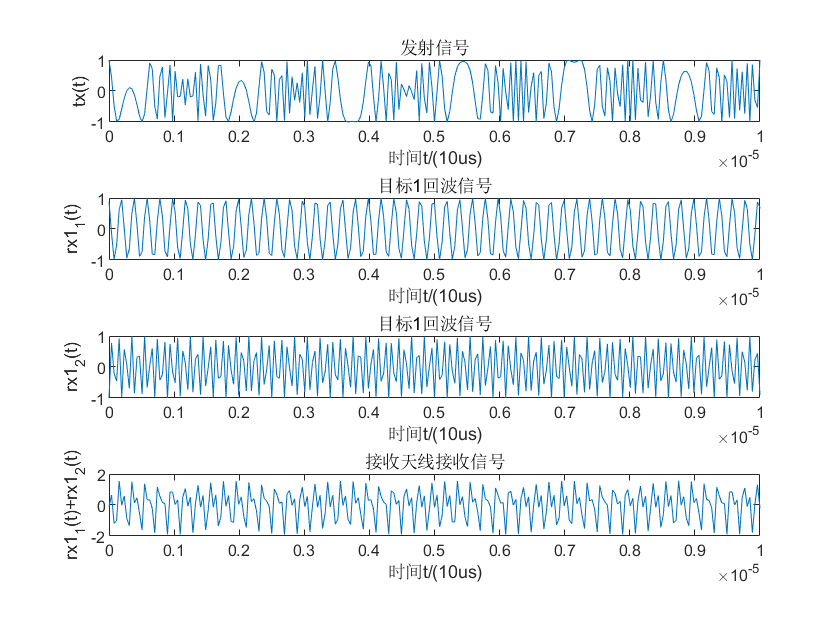


figure
subplot(4,1,1)
p1 = plot(t, real(signal_t));
title('发射信号');
xlim([0 0.1e-4]);xlabel('时间t/(10us)');ylabel('tx(t)');
subplot(4,1,2)
p2 = plot(t, real(signal_1));
title('目标1回波信号');
xlim([0 0.1e-4]);xlabel('时间t/(10us)');ylabel('rx1_1(t)');
subplot(4,1,3)
p3 = plot(t, real(signal_2));
title('目标1回波信号');
xlim([0 0.1e-4]);xlabel('时间t/(10us)');ylabel('rx1_2(t)');
subplot(4,1,4)
p4 = plot(t,real(mixed{i,j}));
title('接收天线接收信号');
xlim([0 0.1e-4]);xlabel('时间t/(10us)');ylabel('rx1_1(t)+rx1_2(t)');

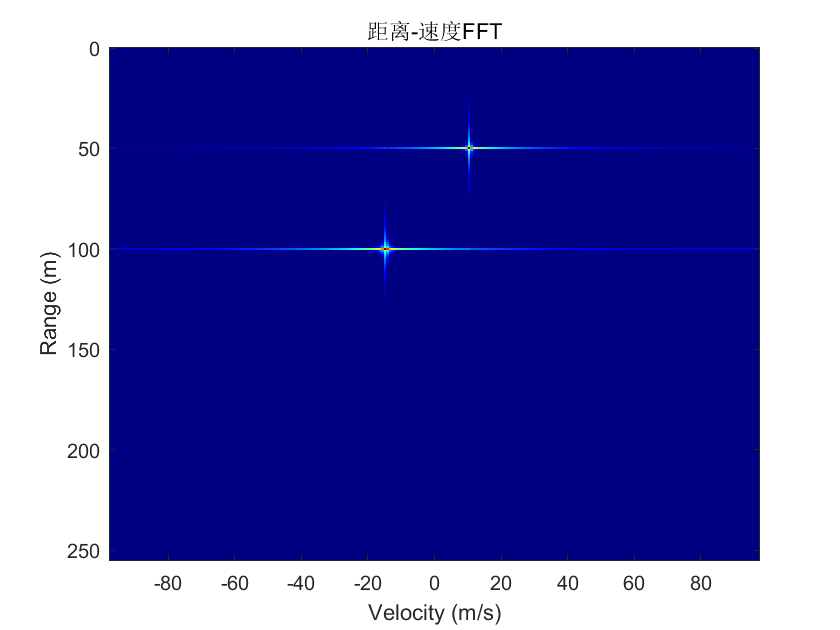

%=====================================距离-速度二维FFT变换===========================%
%N_range行FFT变换；N_dopp列FFT变换，N_azimuth方位角
N_Dopp = numChirps; % length of doppler FFT
N_range = numADC; % length of range FFT
N_azimuth = numTX*numRX;
R = 0:dR:Rmax-dR; % range axis
V = linspace(-Vmax, Vmax, numChirps); % Velocity axis
ang_ax = -90:90; % angle axis

RDC = reshape(cat(3,mixed{:}),numADC,numChirps*numCPI,numRX*numTX); % radar data cube,融合接收的多个信号
RDMs = zeros(numADC,numChirps,numTX*numRX,numCPI);
for i = 1:numCPI
    RD_frame = RDC(:,(i-1)*numChirps+1:i*numChirps,:);%numADC*frame*numRx个rx通道
    RDMs(:,:,:,i) = fftshift(fft2(RD_frame,N_range,N_Dopp),2);%对前两个维度[numchirp,numADC]做FFT
end

figure
%将256*256的数组元素映射为一个处于同一位置的一个像素
imagesc(V,R,20*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1))))));
colormap(gca,jet(256));
clim = get(gca,'clim');
caxis([clim(1)/2 0]);
title("距离-速度FFT");
xlabel('Velocity (m/s)');ylabel('Range (m)');

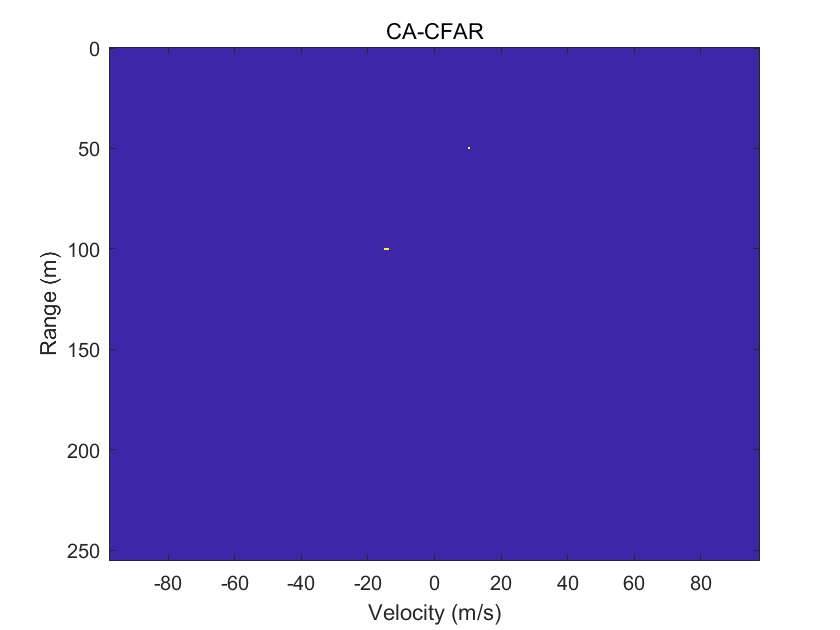

%==========================================CA-CFAR==================================%
numGuard = 2; % 保护单元
numTrain = numGuard*2; % 训练单元
P_fa = 1e-5; % 虚警概率 
SNR_OFFSET = -5; % dB
RDM_dB = 10*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1)))));

[RDM_mask, cfar_ranges, cfar_dopps, K] = ca_cfar(RDM_dB, numGuard, numTrain, P_fa, SNR_OFFSET);%返回去噪后的帧信号，目标准确目标[cfar_ranges, cfar_dopps]，目标数K

figure
h=imagesc(V,R,RDM_mask);
title('CA-CFAR');
xlabel('Velocity (m/s)');ylabel('Range (m)')

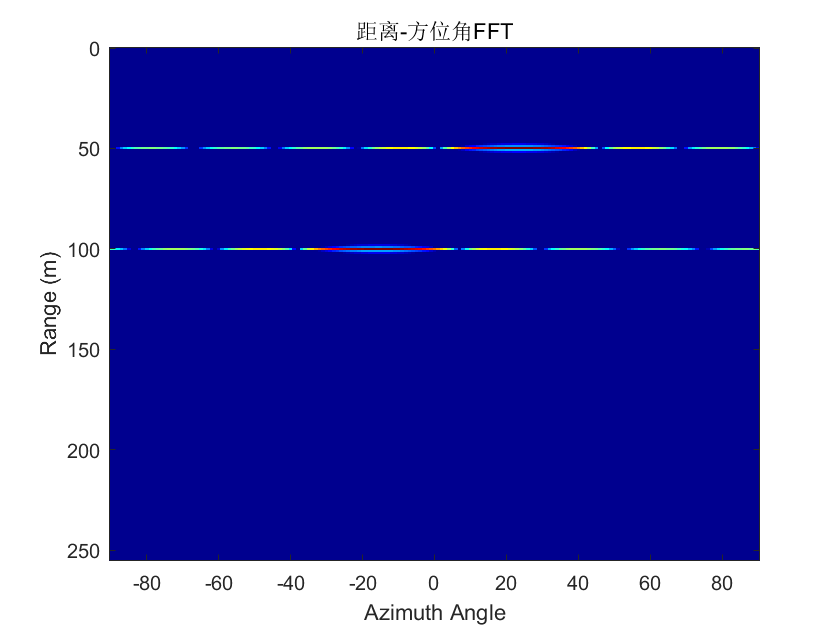

%%====================================距离-方位角二维FFT=====================================
rangeFFT = fft(RDC(:,1:numChirps,:),N_range);%对一组chirp沿着numADC做FFT
angleFFT = fftshift(fft(rangeFFT,length(ang_ax),3),3);%对一组chirp沿着rx做FFT
range_az = squeeze(sum(angleFFT,2)/numChirps); % 距离-方位FFT图

figure
imagesc(ang_ax,R,20*log10(abs(range_az)./max(abs(range_az(:))))); 
colormap(jet);
set(gca,'clim', [-35, 0]);
title('距离-方位角FFT');
xlabel('Azimuth Angle');ylabel('Range (m)');

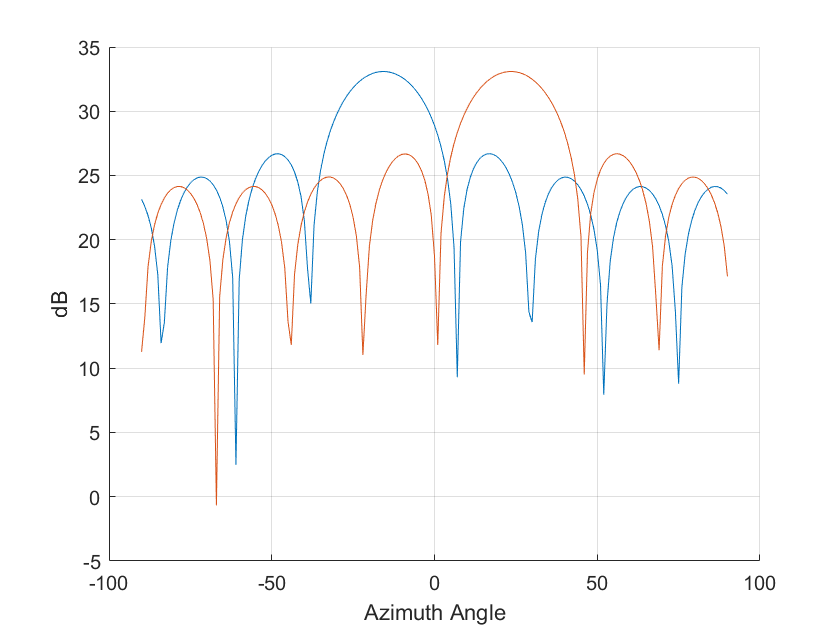


%对CA-CFAR结果目标
doas = zeros(K,181); 
figure
hold on; grid on;
for i = 1:K
    doas(i,:) = fftshift(fft(rangeFFT(cfar_ranges(i),cfar_dopps(i),:),181));
    plot(ang_ax,10*log10(abs(doas(i,:))));
end
xlabel('Azimuth Angle');ylabel('dB');

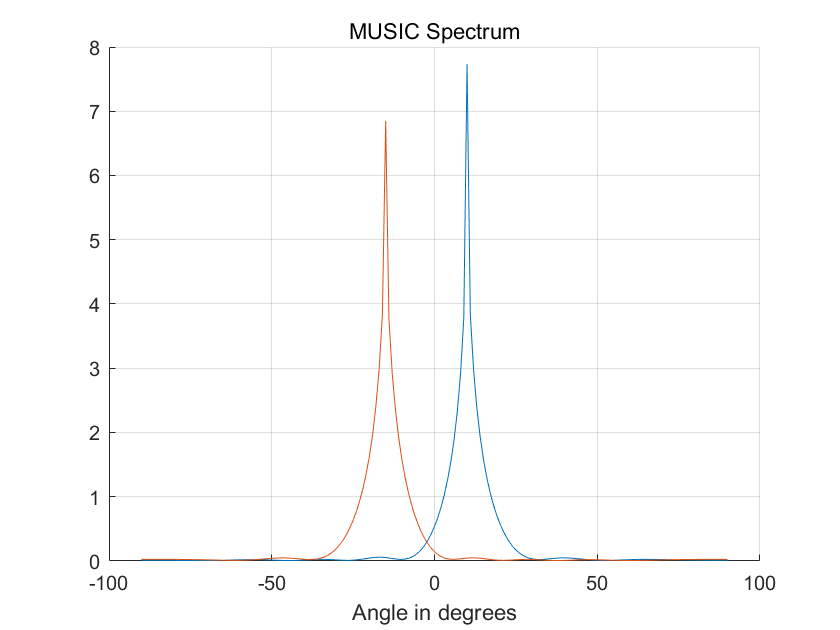

%%==========================AOA 估计 - MUSIC算法==========================
d = 0.5;
M = numCPI; % 

%构造搜索导向矩阵
%假设目标出现在导向矩阵构造的的列的角度上
for k=1:length(ang_ax)
        a1(:,k)=exp(-1i*2*pi*(d*(0:numTX*numRX-1)'*sin(ang_ax(k).'*pi/180)));
end
 
for i = 1:K
    Rxx = zeros(numTX*numRX,numTX*numRX);
    for m = 1:M
       %计算接收信号的自相关矩阵（对numCPI求平均），对最优[cfar_ranges(i),cfar_dopps(i)]位置的不同rx构成向量
       A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,m));
       Rxx = Rxx + 1/M * (A*A');
    end
    %求信号自相关矩阵，获得噪声的特征向量
    [Q,D] = eig(Rxx); % Q:特征向量, D: 对角元素为特征值
    [D, I] = sort(diag(D),'descend');
    Q = Q(:,I); 
    Qs = Q(:,1:2); % 获得信号特征向量，为什么是1？此时两个回波载波频率不同，其自相关矩阵rank=2
    Qn = Q(:,3:end); % 噪声特征向量
    
    %MUSIC空间谱
    for k=1:length(ang_ax)
        music_spectrum(i,k)=(a1(:,k)'*a1(:,k))/(a1(:,k)'*(Qn*Qn')*a1(:,k));
    end
end

figure
hold on 
grid on
title('MUSIC Spectrum')
xlabel('Angle in degrees')
for k = 1:K
    plot(ang_ax,log10(abs(music_spectrum(k,:))));
end

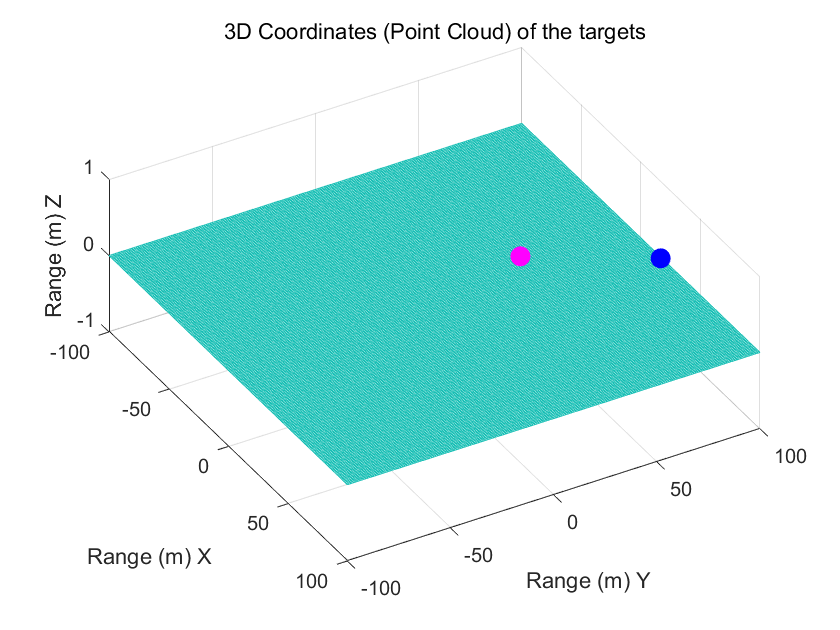

%%================================生成点云=================================
[~, I] = max(music_spectrum(2,:));
angle1 = ang_ax(I);
[~, I] = max(music_spectrum(1,:));
angle2 = ang_ax(I);

coor1 = [cfar_ranges(2)*sind(angle1) cfar_ranges(2)*cosd(angle1) 0];
coor2 = [cfar_ranges(1)*sind(angle2) cfar_ranges(1)*cosd(angle2) 0];
figure
mesh(-100:1:100,-100:1:100,zeros(201));
hold on;
scatter3(coor1(1),coor1(2),coor1(3),100,'m','filled','linewidth',9)
scatter3(coor2(1),coor2(2),coor2(3),100,'b','filled','linewidth',9)
title('3D Coordinates (Point Cloud) of the targets');
xlabel('Range (m) X');ylabel('Range (m) Y');zlabel('Range (m) Z');
view(60,60);

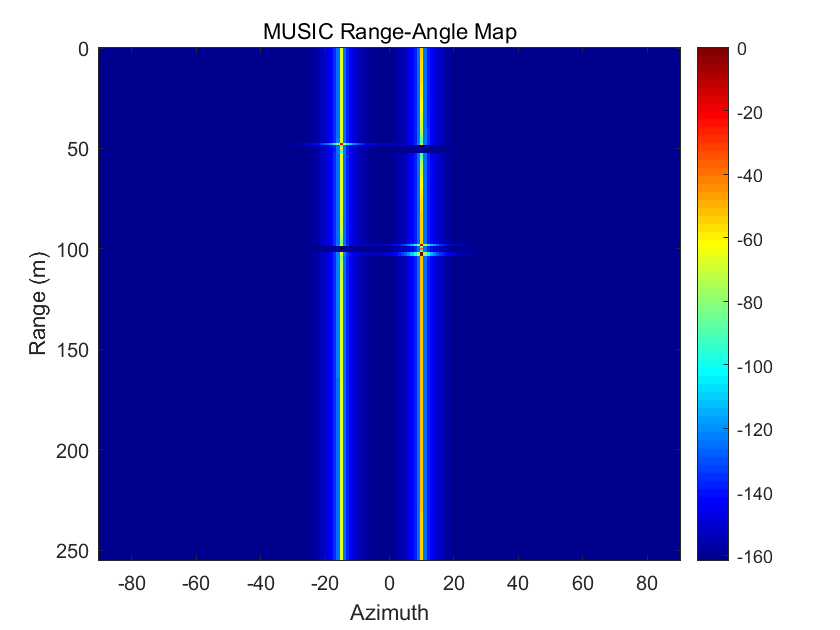


%%=====================================MUSIC 距离-方位角图=================================
rangeFFT = fft(RDC);
range_az_music=zeros(N_range,length(ang_ax));
for i = 1:N_range
    Rxx = zeros(numTX*numRX,numTX*numRX);
    for m = 1:M
       %对每一行（ADC）,将列压缩成每一个向量[numRx]作为输出信号
       A = squeeze(sum(RDMs(i,:,:,m),2));
       %A = squeeze(sum(rangeFFT(i,(m-1)*numChirps+1:m*numChirps,:),2));
       Rxx = Rxx + 1/M * (A*A');
    end
    [Q,D] = eig(Rxx);
    [D, I] = sort(diag(D),'descend');
    Q = Q(:,I);
    index=0;
    for j=1:length(D)-1
        if((D(j)-D(j+1))/D(j)>0.999 && D(j)>=1)
            index=j;
            break
        end
    end
    if(index==0)
        Qn=Q;
    end
    Qn = Q(:,index+1:end);

    for k=1:length(ang_ax)
        range_az_music(i,k)=(a1(:,k)'*a1(:,k))/(a1(:,k)'*(Qn*Qn')*a1(:,k));
    end
end

figure
imagesc(ang_ax,R,20*log10(abs(range_az_music)./max(abs(range_az_music(:)))));
colormap(jet);colorbar;
clim = get(gca,'clim');
title('MUSIC Range-Angle Map');
xlabel('Azimuth');ylabel('Range (m)');

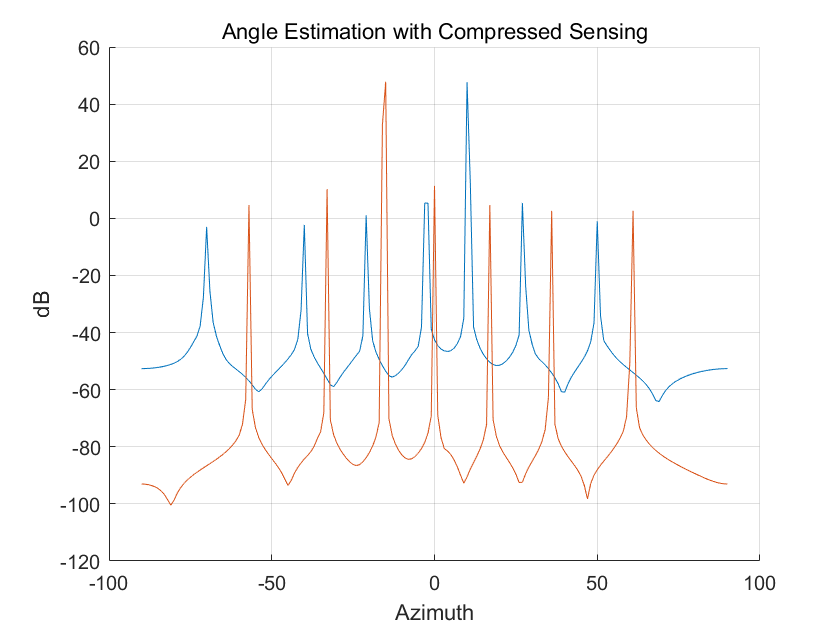

 
Calling SDPT3 4.0: 561 variables, 17 equality constraints
------------------------------------------------------------

 num. of constraints = 17
 dim. of socp   var  = 560,   num. of socp blk  = 182
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+00|1.3e+01|1.9e+07| 1.262844e+06  0.000000e+00| 0:0:00| chol  1  1 
 1|0.928|0.939|7.5e-02|1.2e+00|2.6e+06| 1.143083e+06  1.015074e+05| 0:0:01| chol  1  1 
 2|0.984|0.929|1.2e-03|3.0e-01|3.3e+05| 3.056712e+05  7.682120e+04| 0:0:01| chol  1  1 
 3|0.724|1.000|3.3e-04|1.2e-01|9.2e+04| 1.387417e+05  6.430570e+04| 0:0:01| chol  1  1 
 4|0.969|

cvx_status = 'Solved'

cvx_optval = 5.8380e+04

 
Calling SDPT3 4.0: 561 variables, 17 equality constraints
------------------------------------------------------------

 num. of constraints = 17
 dim. of socp   var  = 560,   num. of socp blk  = 182
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+00|1.3e+01|2.0e+07| 1.342839e+06  0.000000e+00| 0:0:00| chol  1  1 
 1|0.929|0.940|7.4e-02|1.2e+00|2.7e+06| 1.213674e+06  1.075924e+05| 0:0:00| chol  1  1 
 2|0.984|0.929|1.2e-03|3.0e-01|3.4e+05| 3.198105e+05  8.214443e+04| 0:0:00| chol  1  1 
 3|0.701|1.000|3.5e-04|1.2e-01|1.0e+05| 1.515397e+05  6.883492e+04| 0:0:00| chol  1  1 
 4|0.954|

cvx_status = 'Solved'

cvx_optval = 6.2520e+04

%% Angle Estimation - Compressed Sensing
numTheta = length(ang_ax); % divide FOV into fine grid
B = a1; % 导向矩阵
figure
hold on; grid on;
title('Angle Estimation with Compressed Sensing')
xlabel('Azimuth')
ylabel('dB')
for i = 1:K
    A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,1));%对第一个CPI处理，形成阵元收到的信号A
    cvx_begin
        %信号A看做在搜索矩阵列向量B作为基的表示，A=Bs,对于两个目标，
        %目标只会在两个角度，于是s是稀疏的，只需要求稀疏表示即可（求稀疏的K个最大稀疏）
        variable s(numTheta) complex; 
        minimize(norm(s,1))
        norm(A-B*s,2)<=1;
    cvx_end
    cvx_status
    cvx_optval
    plot(ang_ax,10*log10(abs(s)))
end